# Supervised Learning - Week 3 / Part 1

## 1 - Classification with Logistic Regression

Previously we've learnt about linear regression, which means that we try to predict a continuous number as accurately as possible. Now, we will learn about classification, where we will try to predict the value of an output is a member of a finite set of values. It is important to note that after trying linear regression algorithm in classification problems, we realized that the linear regression is not what we need for classificaiton. Let's take a look at why this is the case first. Then, we will take a look at an another algorithm called "logistic regression", which is one of the most popular classification algortihm.

Let's take a look at some examples of classification problems:

In each of the examples above, the variable we'd like to predict can only take two values: Yes or No. This kind of classification problem where there are only two possible outcomes is called "binary classification". In those problems we will use the terms "class" and "category" interchangeably. We often designate the classes in a logical fashion such as Yes = true (1 or "positive class") and No = false (0 or "negative class"). From now on, we will use the 0 and 1 notation to represent $y$ since it is the simpliest way to implement the numerical values into our learning algorithms. 

- Please note that negative and positive classes not necessarily mean evil versus good. Normally any selection of the labelling shouldn't affec the training and/or the performance of the algorithm.

### How do we create a classification algorithm?

Let's check the dataset for classifying whether the tumor is malignant or benign. The class 1 (positive class) will represent malignant and class 0 (negative class) will represent a benign tumor.

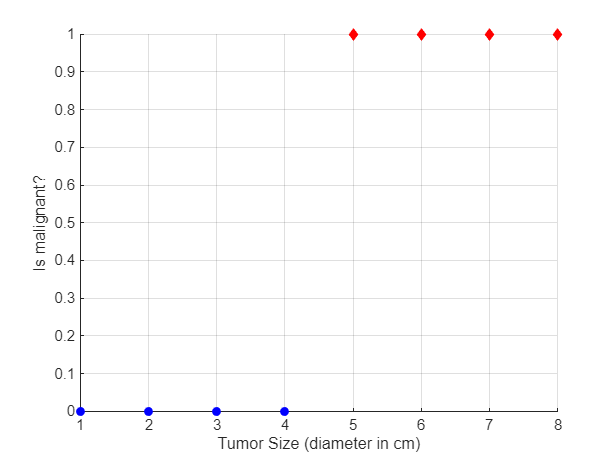

x = 1:8;
y = [0 0 0 0 1 1 1 1];

y_neg = y(y==0);
x_neg = x(y==0);
y_pos= y(y==1);
x_pos = x(y==1);

figure;
scatter(x_neg,y_neg,'bo','filled')
hold on
scatter(x_pos,y_pos,'rd','filled')
xlabel('Tumor Size (diameter in cm)')
ylabel('Is malignant?')
hold off
grid on

The figure above could be simplified in a 1-D plot as follows:

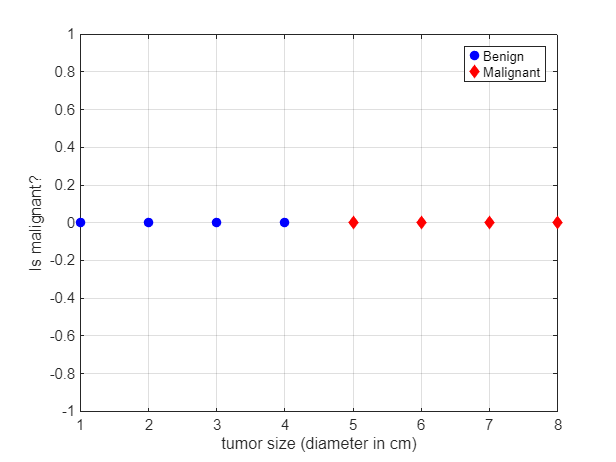

figure;
plot(x_neg,y_neg,'bo','MarkerFaceColor','b')
hold on
plot(x_pos,y_pos-1,'rd','MarkerFaceColor','r')
xlabel('tumor size (diameter in cm)')
ylabel('Is malignant?')
legend('Benign','Malignant')
hold off
grid on

Let's assume if we run our linear regression algorithm in this dataset we will see the following plot:

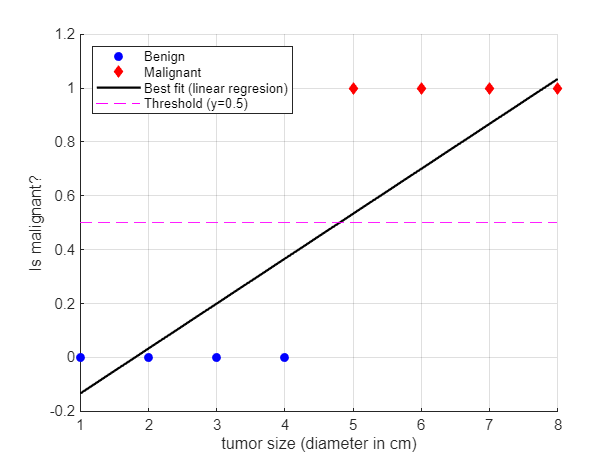

figure;
scatter(x_neg,y_neg,'bo','filled') % data set
hold on
scatter(x_pos,y_pos,'rd','filled')
xlabel('tumor size (diameter in cm)')
ylabel('Is malignant?')
% Let's asssume that we know the parameters of the linear regression w =
% 0.1667 and b = 0.3 for the given data set and if we plot the fit
y = (0.1667).*x-0.3;
plot(x,y,'k','LineWidth',1.5) % linear regression plot
line(x,repmat(0.5,1,length(x)),'Color','magenta','LineStyle','--') % threshold
legend('Benign','Malignant','Best fit (linear regresion)','Threshold (y=0.5)','Location','northwest')
hold off
grid on

- We can note from the above figure that linear regression not only predicts discrete classes but any continuous value. However, we need to pick the right categories.

One thing to do could be picking a threshold value say 0.5, and floor the numbers under the threshold to 0 and ceil above the threshold to 1. Hence, the thresholding rule becomes:

if $f_{w,b}(x) < 0.5$, $\hat{y} = 0$,

if if $f_{w,b}(x) \geq 0.5$, $\hat{y} = 1$

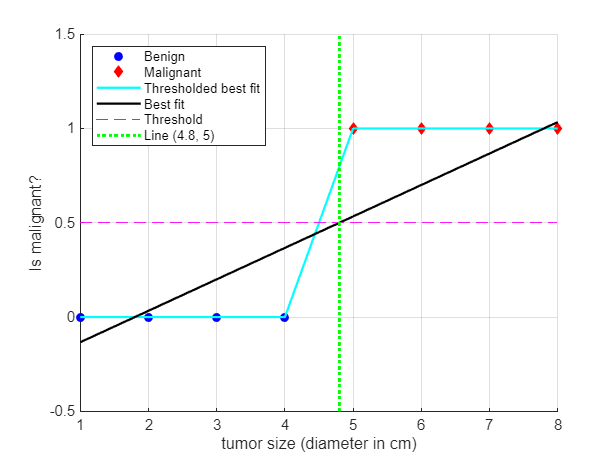

figure;
scatter(x_neg,y_neg,'bo','filled')
hold on
scatter(x_pos,y_pos,'rd','filled')
xlabel('tumor size (diameter in cm)')
ylabel('Is malignant?')

% Let's asssume that we know the parameters of the linear regression w =
% 0.1667 and b = 0.3 for the given data set and if we threshold (0.5) the
% results
y = (0.1667).*x-0.3;
y(y>=0.5) = 1;
y(y<0.5) = 0;
plot(x,y,'c-','LineWidth',1.5) % thresholded best fit
y = (0.1667).*x-0.3;
plot(x,y,'k','LineWidth',1.5) % best fit
line(x,repmat(0.5,1,length(x)),'Color','magenta','LineStyle','--')
line([4.8 4.8],[-0.5 1.5],'Color','g','LineStyle',':','LineWidth',2)
legend('Benign','Malignant','Thresholded best fit','Best fit','Threshold','Line (4.8, 5)','Location','northwest')
hold off
grid on

- Note also that the threshold line intersects the fitted line at the point $(4.8,~5)$. Therefore, every tumor size that is less that 4.8 ends up being predicted as "benign" and every tumor size that is larger than or equal to 4.8 end up being predicted as "malignant".

- In this particular data set it looks like linear regression algorithm could predict the class of the tumors with a relatively reasonable accuracy.

However, what if we had one more data training example:

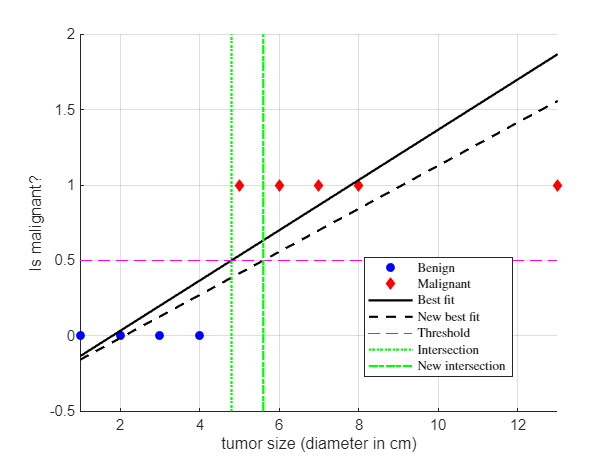

x = [1:8 13];
y = [0 0 0 0 1 1 1 1 1];

y_neg = y(y==0);
x_neg = x(y==0);
y_pos= y(y==1);
x_pos = x(y==1);

figure;
scatter(x_neg,y_neg,'bo','filled')
hold on
scatter(x_pos,y_pos,'rd','filled')
xlabel('tumor size (diameter in cm)')
ylabel('Is malignant?')
y = (0.1667).*x-0.3;
y_new = (0.1429).*x-0.3;
plot(x,y,'k','LineWidth',1.5)
plot(x,y_new,'k--','LineWidth',1.5)
line(x,repmat(0.5,1,length(x)),'Color','magenta','LineStyle','--')
line([4.8 4.8],[-0.5 2],'Color','g','LineStyle',':','LineWidth',1.5)
line([5.5983 5.5983],[-0.5 2],'Color','g','LineStyle','-.','LineWidth',1.5)
xlim([min(x) max(x)])
legend('Benign','Malignant','Best fit','New best fit','Threshold','Intersection','New intersection','Interpreter','Latex','Location','best')
hold off
grid on

- Note that this new data point shouldn't change how we classify the other data points. However, once we add this extra training example the best fit line's slope will become smaller. Therefore, the new threshold value, which is the point of intersection between the best fit line and the 0.5 threshold has shifted towards right hand side.

- Consequently, the positive class (Malignant) training sample right next to the green line in the above plot will now classified as a negative class (Benign).

- This is not what we want since adding a new example of one particular class shouldn't change (in a negative way) any of our conclusions about how to classify "Benign" and "Malignant" tumors.

- If we approach a classification problem with a linear regression algorithm we end up having a much worse best fit line every single time we add a training sample, which causes a big misclassification issue. Sometimes you might get lucky and linear classification work with the given data, however, often we need a different algorithm to approach the classification problems for better classification accuracy.

Next we will learn about the decision boundary and logistic regression algorithms.

### 1.1 - Lab: Classification Using Linear Regression

In this lab we will see the differences between the regression and classification problems. In order to do that we will run the linear regression algorithm on a classification dataset and observe if the best fit could be useful for binary classification of the data. The markers in the classification data set is often used to indicate the predicted outcome of a sample/example. 

In the plots below, 'x' will be used to represent the positive class and 'o' will be used to prepresent negative class samples.

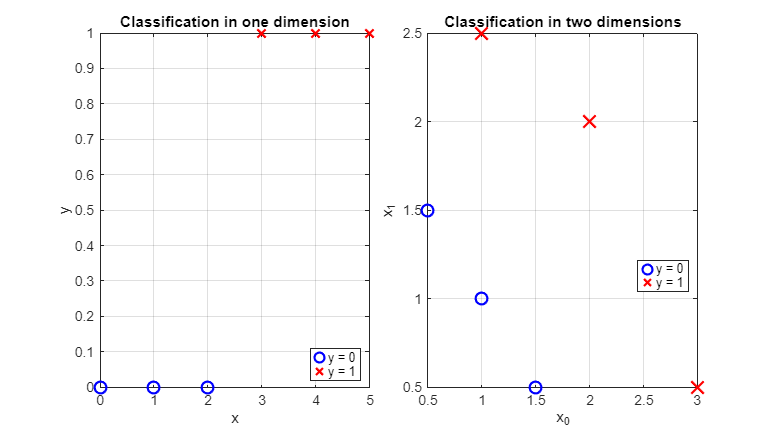

% Generate the dataset
X_train = [0, 1, 2, 3, 4, 5].';
y_train = [0, 0, 0, 1, 1, 1];

X_train2 = [0.5, 1.5; 1, 1; 1.5, 0.5; 3, 0.5; 2, 2; 1, 2.5];
y_train2 = [0, 0, 0, 1, 1, 1];

% Plot - 1 (single dimensional classification)
f = figure;
tiledlayout(1,2,"TileSpacing","compact")
nexttile
hBinaryScatter(X_train,y_train,{'x','o'},{'r','b'},8)
legend('y = 0','','','y = 1','','','Location','best')
xlabel('x')
ylabel('y')
title('Classification in one dimension')
grid on

% Plot - 2 (Two dimensional classification)
nexttile
hBinaryScatter(X_train2,y_train2,{'o','x'},{'b','r'},8)
legend('y = 0','','','y = 1','','','Location','best')
xlabel('x_0')
ylabel('x_1')
title('Classification in two dimensions')
grid on
f.Position = [0 0 700 400];

**Observation - 1:** In the single variable plot, the positive examples are represented by red crosses (y=1), where the negative examples are shown by blue circles (y=0).

- If we can recall from the linear regression problem, the values of the y is not only taking two values but it can take any continuous value.

**Observation - 2:** In the second plot, the y-axis is not available. The positive and negative samples are also shown by using the same notation convention.

- In the case of  linear regression with multiple variables, y would not be limited to only two values and a similar plot would be three dimensional.

### Linear Regression Approach for Classification Problem

In the previous weeks we built a prediction model, which had ability to do linear regression using batch gradent descent algorithm. Let's try the same approach here to a classificaiton problem. The model has to predict if a tumor is benign or malignant based on the tumor size. Try the following steps:

- Run single varible linear regression algorithm on the given data. Note that the resulting linear model **does not** match the data well. One option to improve the results is the introduce a threshold.

- Set the activate the threshold and set it to 0.5 to observe the predictions when threshold is applied. Those predictions look better, the predictions now match the data.

 

threshold = true; % Toggle 0.5 threshold after regression
X_train = [0 1 2 3 4 5 20].';
y_train = [0 0 0 1 1 1 1];
alpha = 0.01;
[J_vec,w_vec,b_vec] = hGeneralizedBatchGradientDescent(X_train,y_train,alpha,initMethod="zero",iter_stop=515,verboseFreq=100);

Iteration #0 | Cost: 0.14271
Iteration #100 | Cost: 0.096734
Iteration #200 | Cost: 0.088944
Iteration #300 | Cost: 0.086661
Iteration #400 | Cost: 0.085992
Iteration #500 | Cost: 0.085796
* BGD stopped: max number of iterations (514)
Parameters found using BGD w: [ 0.0440 ], b: 0.3422


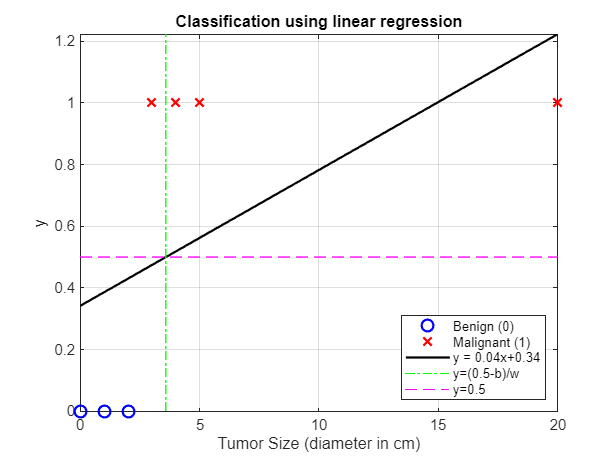

% Plot (single dimensional classification plus linear regression fit)
figure;
hBinaryScatter(X_train,y_train,{'x','o'},{'r','b'},8)
hold on
plot(0:max(X_train),(w_vec(end).*(0:max(X_train))+b_vec(end)),'k',"LineWidth",1.5)
if threshold
    line([(0.5-b_vec(end))/w_vec(end) (0.5-b_vec(end))/w_vec(end)],[0 w_vec(end)*max(X_train)+b_vec(end)],'Color','g','LineStyle','-.')
    line(X_train,repmat(0.5,1,length(X_train)),'Color','magenta','LineStyle','--')
end
ylim([0 w_vec(end).*max(X_train)+b_vec(end)])
legend('Benign (0)','','','Malignant (1)','','','',['y = ', num2str(round(w_vec(end),2)),'x+',num2str(round(b_vec(end),2))],'y=(0.5-b)/w','y=0.5','Location','southeast')
xlabel('Tumor Size (diameter in cm)')
ylabel('y')
title('Classification using linear regression')
grid on
hold off

- **Important note:** Add more 'malignant' data points on the far right, in the large tumor size range (near  10 cm), and re-run the BGD based linear regression algortihm. Now the model predict the large tumor correctly, however, the data point at x = 3 is being incorrectly predicted.

- This clearly shows us adding "better" (large tumor size) malignant samples should be making model predictions more accurate, whereas in our case it played and adversarial effect. Therefore, we can conclude that the linear regression algorithm is not sufficient to model such a categorical data.

## 2 - Logistic Regression

Let's now talk about the logistic regression algorithm, which is probably the most used classification algorithm in the world. Let's continue with the tumor classification example to determine whether a tumor is malignant (1) or benign (0).

- We saw that in the previous lab that the linear regression is not a robust algorithm to be used in classification problems.

- In contrast, what logistic regression algorithm does it to fit an "S-shaped" curve to the dataset. This "S-shaped" curve is called **sigmoid function** or **logistic function.** Why do need an "S-shaped" curve, can't we just use a sign/step function? The reasoning behind the sigmoid function is it's simple derivative, which we will show in the following. 

The sigmoid (logistic) function could be defined as follows:

$g(x) = \frac{1}{1+e^{-x}}$, where the domain and range of the sigmoid function becomes $g(x):~(-\infty,~\infty) \rightarrow [0,~1]$.

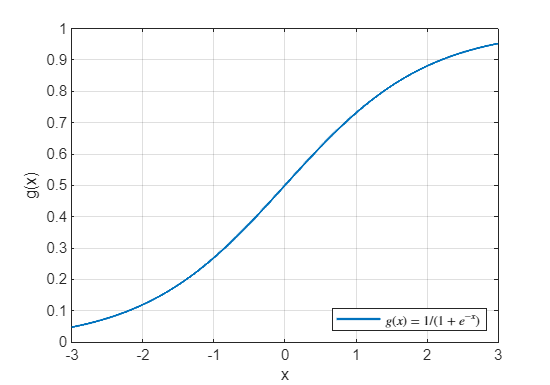

x = -3:0.001:3;
g = 1./(1+exp(-x));
f = figure;
plot(x,g,'LineWidth',1.5)
grid on
xlabel('x')
ylabel('g(x)')
legend('$g(x)=1/(1+e^{-x})$','Interpreter','latex','Location','southeast')
f.Position = [0 0 500 350];

Let's use the sigmoid function to build up the logistic regression algorithm. We will do this in two steps:

**Step 1** -  A linear regression function could be defined as $z =  \mathbf{x}\mathbf{w} + b$ where $\mathbf{x}$ and $\mathbf{w}$ are the $1 \times n$ features and $n \times 1$weights vectors, respectively. We store the result of linear regression in a variable $\mathbf{z}$. Let's pass this varible into the sigmoid function,

$g(z) = \frac{1}{1+e^{-z}}$. 

Now, our output $g(\mathbf{z})$ will always be in the range of 0 and 1.

**Step 2** - If we combine those two expressions we had above we will have the logistic regression formula,

 $f_{\mathbf{w},b}(\mathbf{x}) = g(\mathbf{x}\mathbf{w}+b) 
= \frac{1}{1+e^{-\left(\mathbf{x}\mathbf{w}+b\right)}}$, where this is the logistic regression model. It inputs a feature(s) and outputs a value that is in the range of $[0 \quad 1]$.

- Now, let's take a look at how to interpret the output of the logistic regression. The output value of the logistic regression model can be compared with the class values 0 and 1 to determine the final decision (Euclidean distance between the output of the logistic function and the target values).

- An alternative interpretation of the logistic regression model's output is to consider it as the** probability that the given class is 1 (probability of the positive class)**, which can be represented as $f_{\mathbf{w},b}(x) = P(y=1 ~|~ \mathbf{x};\mathbf{w},b)$. For example, if a patient has a certain tumor size and the model outputs $f_{\mathbf{w},b}(\mathbf{x}) = 0.7$, it means there is a 70% probability that the patient's tumor is malignant (30% probability that the patient's tumot is benign).

- The final classification is determined by whether the output value is closer to 0 or to 1, $y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } g(\mathbf{x}\mathbf{w} + b) \geq 0.5  \\
        0, & \text{if } g(\mathbf{x}\mathbf{w} + b) < 0.5
    \end{array}$    .

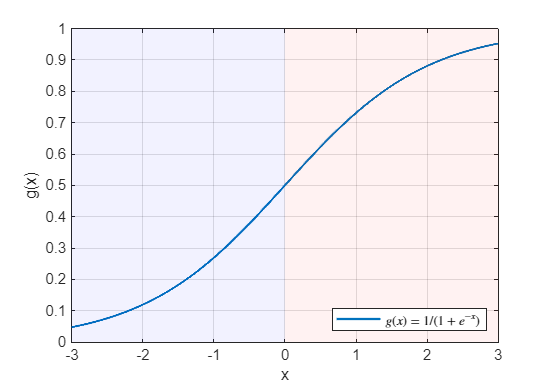

x = -3:0.001:3;
g = 1./(1+exp(-x));
f = figure;
plot(x,g,'LineWidth',1.5)
hold on
patch('Faces',[1 2 3 4],'Vertices',[-3 0; 0 0; 0 1; -3 1],'FaceColor','blue','FaceAlpha',0.05,'EdgeColor','none')
patch('Faces',[1 2 3 4],'Vertices',[0 0; 3 0; 3 1; 0 1],'FaceColor','red','FaceAlpha',0.05,'EdgeColor','none')
hold off
grid on
xlabel('x')
ylabel('g(x)')
legend('$g(x)=1/(1+e^{-x})$','Interpreter','latex','Location','southeast')
f.Position = [0 0 500 350];

## 3 - Decision Boundary

In the previous section we've learnt about the logistic regression model. In this section let's learn about the **"decision boundary"** to get a better understanding about how logistic regression generates its predictions. 

Let's recap how the logistic regression algorithm computes its predictions in two steps:

1) Calculate $f_{\mathbf{w},b}( \mathbf{x} ) = g(z) = g(\mathbf{x}\mathbf{w}+b)
= \frac{1}{1+e^{-\left(\mathbf{x}\mathbf{w}+b\right)}}
= P(y=1~|~\mathbf{x};\mathbf{w},b)$, where we interpret the output as the probability that $y$ is equal to 1.

What do we want algorithm to predict? Is the value of $y$ going to be 0 or 1?

2) In order to do the prediction is we need a threshold to make a decision such that:


$$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } f_{\mathbf{w},b}(\mathbf{x}) \geq \text{Threshold}  \\
        0, & \text{if } f_{\mathbf{w},b}(\mathbf{x}) < \text{Threshold}
    \end{array}$$


where the threshold is chosen to be 0.5. We can also express the above expression as follows:

$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } g(z) \geq 0.5  \\
        0, & \text{if } g(z) < 0.5
    \end{array}$    .

We can look at the sigmoid function plot and infer the following:

$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } z \geq 0  \\
        0, & \text{if } z < 0
    \end{array}$ or $y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } \mathbf{x}\mathbf{w} + b \geq 0  \\
        0, & \text{if } \mathbf{x}\mathbf{w} + b < 0
    \end{array}$ 

Given the above expression, we can visualize how the logistic regression algorithm makes its predictions. Let's look at the following example

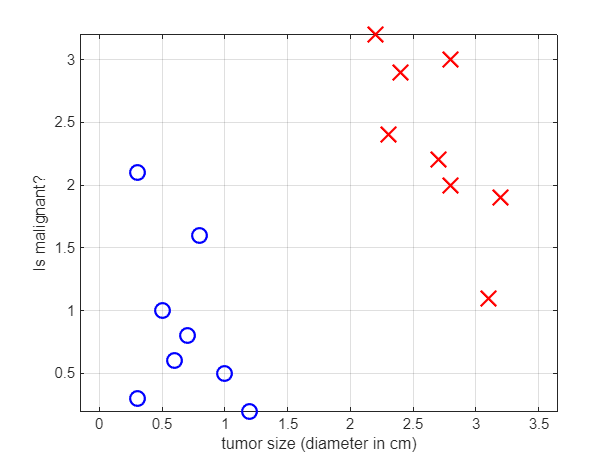

% Generate the dataset
X = [0.3 0.3; 0.6 0.6; 0.5   1; 1   0.5; 0.7 0.8; 0.3 2.1; 1.2 0.2; 0.8 1.6;...
     3.1 1.1; 2.7 2.2; 2.4 2.9; 3.2 1.9; 2.8   3; 2.8   2; 2.3 2.4; 2.2 3.2];
y = [0; 0; 0; 0; 0; 0; 0; 0;...
     1; 1; 1; 1; 1; 1; 1; 1];

figure;
hBinaryScatter(X,y,{'o','x'},{'b','r'},10)
xlabel('tumor size (diameter in cm)')
ylabel('Is malignant?')
grid on
axis equal

On the figure above, the red crosses corresponds to $y=1$ and blue circles corresponds to $y=0$. Thus, the logistic regression algorithm will make decisions based on the following expression: $f_{\mathbf{w},b}(\mathbf{x}) = g(z) = g(w_1x_1 + w_2x_2 +b)$. For this example let's assume that $w_1 = w_2 = 1$ and $b=-3$.

Now, let's take a look how logistic regression makes predictions using the parameters given above. Let's look at where $\mathbf{x}\mathbf{w} + b \geq 0$ and where $\mathbf{x}\mathbf{w} + b < 0$ by using $z = \mathbf{x} \mathbf{w} +b = 0$. It turns out that the that the line $\mathbf{x} \mathbf{w} +b = 0$ is also called the decision boundary.

$z = \mathbf{x} \mathbf{w} +b = w_1x_1 + w_2x_2 + b = x_1 + x_2 - 3 = 0$, which also means that $x_1 + x_2 = 3$.

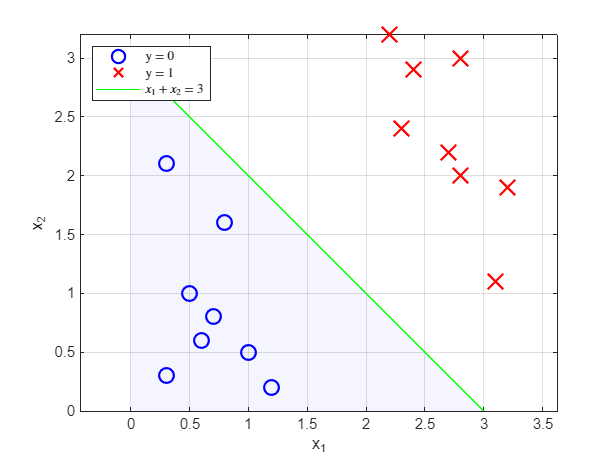

% Generate the dataset
X = [0.3 0.3; 0.6 0.6; 0.5   1; 1   0.5; 0.7 0.8; 0.3 2.1; 1.2 0.2; 0.8 1.6;...
     3.1 1.1; 2.7 2.2; 2.4 2.9; 3.2 1.9; 2.8   3; 2.8   2; 2.3 2.4; 2.2 3.2];
y = [0; 0; 0; 0; 0; 0; 0; 0;...
     1; 1; 1; 1; 1; 1; 1; 1];

figure;
hBinaryScatter(X,y,{'o','x'},{'b','r'},10)
xlabel('x_1')
ylabel('x_2')
grid on
hold on
x1 = 0:3;
plot(x1,3-x1,'g')
area(0:3,3-x1,'EdgeColor','green','FaceColor','blue','FaceAlpha',0.04)
hold off
legend('y = 0','','','','','','','','y = 1','','','','','','','','$x_1+x_2 = 3$','Interpreter','latex','Location','northwest')
axis equal

We know that if $x_1 + x_2 > 3$, the output becomes $y = 1$ and if $x_1 + x_2 < 3$, the output becomes $y = 0$. In other words, we have visualized the decision boundary for the logistic regression for the parameters $w_1 = 1$, $w_2 = 1$, and $b = -3$. If we had picked the parameters differently we would have a completely different decision boundary.

### 3.1 Non-linear Decision Boundaries

Let's look at another example where the decision boundary has to be non-linear.

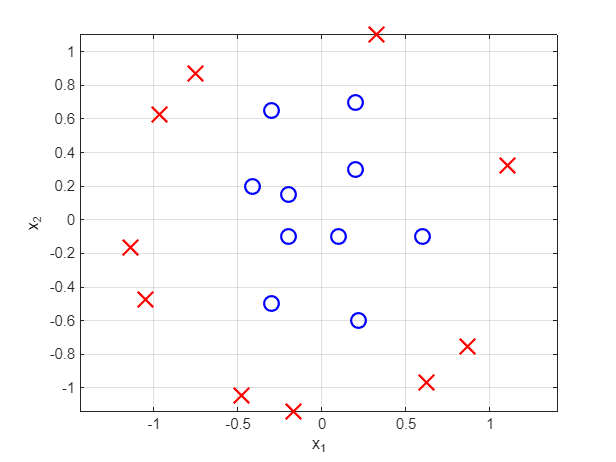

% Generate the dataset
X = [0.1 -0.1; 0.2 0.3; 0.22 -0.6; -0.41 0.2; -0.2 0.15; 0.2 0.7; -0.3 0.65; -0.3 -0.5; -0.2 -0.1; 0.6 -0.1;...
    [1.15*real(exp(-(1i*(1:10))).') 1.15*imag(exp(-(1i*(1:10))).')]];
y = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0;...
     1; 1; 1; 1; 1; 1; 1; 1; 1; 1];

figure;
hBinaryScatter(X,y,{'o','x'},{'b','r'},10)
xlabel('x_1')
ylabel('x_2')
grid on
axis equal

Note from the above figure that the decision boundary cannot longer be a straight line. In the previous lessons, we saw how to use polynomials in non-linear function regression using feature engineering. We can simply do the same using the logistic regression. Let's set  $z = w_1x_1^2 + w_2x_2^2 + b$, which is a polynomial logistic regression. Moreover, $f_{\mathbf{w},b}(\mathbf{x}) = g(z) = g(w_1x_1^2 + w_2 x_2^2 + b)$. Let's say we end up choosing $w_1 = 1$, $w_2 = 1$, and $b = -1$. Thus, $z = x_1^2 + x_2^2 -1$ where the decision boundary can be found by  $z = x_1^2 + x_2^2 -1 = 0$. In other words, $x_1^2 + x_2^2 = 1$. If we treat $x_1$ and $x_2$ as independent and dependent variables, $|x_2| = \sqrt(1-x_1^2)$, which can be represented by

$x_2 = 
\left\{
    \begin{array}{lr}
        \sqrt(1-x_1^2), & \text{if } x_2 \geq 0  \\
        -\sqrt(1-x_1^2), & \text{if } x_2 < 0
    \end{array}$    .

If we plot this function,

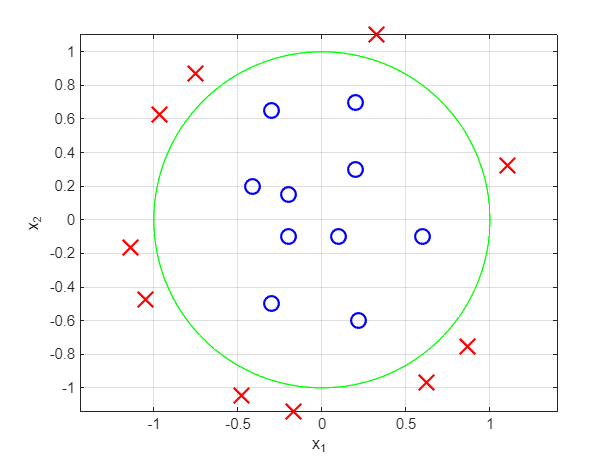

% Generate the dataset
X = [0.1 -0.1; 0.2 0.3; 0.22 -0.6; -0.41 0.2; -0.2 0.15; 0.2 0.7; -0.3 0.65; -0.3 -0.5; -0.2 -0.1; 0.6 -0.1;...
    [1.15*real(exp(-(1i*(1:10))).') 1.15*imag(exp(-(1i*(1:10))).')]];
y = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0;...
     1; 1; 1; 1; 1; 1; 1; 1; 1; 1];

figure;
hBinaryScatter(X,y,{'o','x'},{'b','r'},10)
xlabel('x_1')
ylabel('x_2')
hold on
x2_pos = @(x1) sqrt(1-x1.^2);
x2_neg = @(x1) -sqrt(1-x1.^2);
fplot(x2_pos,[-1 1],'g')
fplot(x2_neg,[-1 1],'g')
hold off
grid on
axis equal

The region $x_1^2 + x_2^2 \geq 1$ corresponds to the outside of the cirlce where we predict $\hat{y} = 1$ and $x_1^2 + x_2^2 < 1$ corresponds to the inside of the circle where we predict $\hat{y} = 0$.

- **Then, the key question is: Can we come up with even more complex decision boundaries than those ones above?**

The answer is yes!

$f_{\mathbf{w},b}(\mathbf{x}) = g(z) = g(w_1x_1 + w_2x_2 + w_3x_1^2 + w_4x_1x_2 + w_5x_2^2)$ or

$f_{\mathbf{w},b}(\mathbf{x}) = g(z) = g(w_1x_1 + w_2x_2 + w_3x_1^2 + w_4x_1x_2 + w_5x_2^2 + w_6x_1^3 + \cdots + b)$, where we can choose any parameters with any order that would correspond to a very complex shapes (decision boundaries) in the 2D/3D spaces. With those polynomial features, we can fit into very complex decision boundaries, where it also means that the logistic regression algorithm will be able to learn a very complex patterns from the data. If we not include the higher order polynomials into account the decision boundary will be linear.

Next, let's take a look how you can train the logistic regression algorithm. In order to do so we will start with the cost function and we will move onto how to implement gradient descent (GD) to the logistic regression.